## Quiz 6 Practice : Nonlinear Equations and Optimization

Question 1: 

Consider the equation:


$$f\left(x\right)=\frac{\left(x-2\right)\left(2x+1\right)}{1+x^2 }$$


Use Newton’s method to find the zeros of f(x) from -5 to 5 and the x-values at which this occurs.

Hint: Choose a proper x0 based on the graph to find one and run again to find the other.

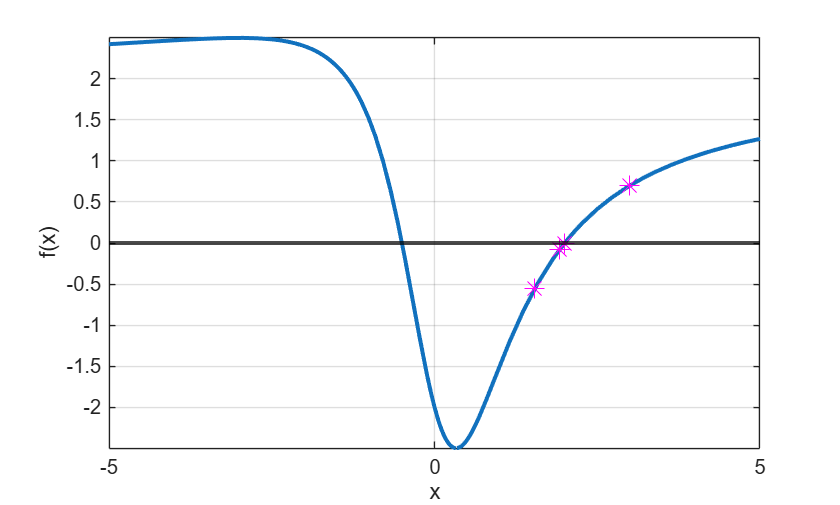

Iteration 1: x = 1.5417, P(x) = 0.7000
Iteration 2: x = 1.9255, P(x) = -0.5542
Iteration 3: x = 1.9978, P(x) = -0.0767
Iteration 4: x = 2.0000, P(x) = -0.0022


Zero found at x = 2.0000 within tolerance 0.01


clear; clc; close all;

    % % Define 
% xr (initial, any but within range)
% maxIter
% maxtol
% tspan
xr = 3;
maxIter = 20;
maxtol = 0.01;
tspan = [-5, 5];

syms x;
P(x) = (x-2)*(2*x+1)/(1+x^2);
dPx(x) = diff(P, x);

% Convert to numerical 
P = matlabFunction(P); 
dPx = matlabFunction(dPx);

%  % Initial Graph to find x0
figure;
fplot(P, tspan, 'linewidth', 2);
hold on;
xlabel('x'); 
ylabel('f(x)');
yline(0, 'LineWidth', 2, 'Color', 'k');
grid on;

% Initial graph suggest one root is around -0.5 and the other around 2 >>>> Pick a value close to one of them


% % Newton's method
for itr = 1:maxIter  % stop at 20

    %Step 1 --- Plot zero
    plot(xr,P(xr),'m*','MarkerSize',10); % Plot guess for zero

    %Step 2 -- Calculate the function and derivative values at the current guess
    P_val = double(P(xr));
    dPx_val = double(dPx(xr));

    %Step 3 -- Prevent division by zero
    if dPx_val == 0
        fprintf('Derivative is zero at x = %.4f. Stopping to avoid division by zero.\n', xr); 
        break;
    end

    %Step 4 -- Newton's method formula
    xr_new = xr - P_val / dPx_val;

    %Step 5 -- Display
    fprintf('Iteration %d: x = %.4f, P(x) = %.4f\n', itr, xr_new, P_val);

    %Step 6 -- Check for convergence / if newton's method found a sufficiently accurate approximation
    if abs(P_val) <= maxtol
        fprintf('Zero found at x = %.4f within tolerance %.2f\n', xr_new, maxtol);
        break;
    end

    % Update x value for the next iteration
    xr = xr_new;
end

Question 2: 

Use SGD code needed to find the minimum and maximum in a span from -5 to 5 of the function:


$$f\left(x\right)=\frac{\left(x-2\right)\left(2x+1\right)}{1+x^2 }$$


Use a tolerance of 0.01 and a step of 0.1.

Hint: Changing the sign switches the direction. Choose a proper x0 to avoid local minima/maxima.

A) Minimum?

clear; clc; 

% GRADIENT DESCENT METHOD!!!
tolx = 0.01;
alpha = 0.1; % stepwise
tspan = [-5, 5];
maxloops = 100;

syms f(x);
f(x) = (x - 2) * (2 * x + 1) / (1 + x^2); % Function definition
dfx(x) = diff(f, x);  % First derivative
d2fx(x) = diff(f, x, 2); % Second derivative

f=matlabFunction(f);
dfx=matlabFunction(dfx);
d2fx=matlabFunction(d2fx);


% STOP HERE FOR INITIAL GUESSES FOR MIN !!!!!!
figure;
fplot(f, tspan, 'LineWidth', 2);
hold on;
xlabel('x'); 
ylabel('f(x)'); 
title('SGD to Find Local Minimum');
grid on;

x0 = -1; % initial guess for MIN

for i = 1:maxloops
    plot(x0, f(x0), 'mo', 'MarkerSize', 10, 'LineWidth', 1.5);

    grad = dfx(x0);
    x1 = x0 - alpha * grad;
    if i == 1
        fprintf('Ite   X0     X1     DFx     D2Fx\n');
    end
    fprintf('%2d %7.3f %7.3f %7.3f %7.3f\n', i, x0, x1, grad, d2fx(x0));
    if abs(x1 - x0) <= tolx || abs(grad) < tolx
        if d2fx(x0) > 0
            disp('Local Minimum');
        else
            disp('Local Maximum');
        end
        break;
    end

    x0 = x1;
end

Ite   X0     X1     DFx     D2Fx


 1  -1.000  -0.800  -2.000  -3.500
 2  -0.800  -0.522  -2.781  -4.237
 3  -0.522  -0.129  -3.927  -3.436
 4  -0.129   0.256  -3.854   5.032
 5   0.256   0.323  -0.664   9.037
 6   0.323   0.331  -0.088   8.254


Local Minimum


fprintf('Final x value: %.4f\n', x1);

Final x value: 0.3314


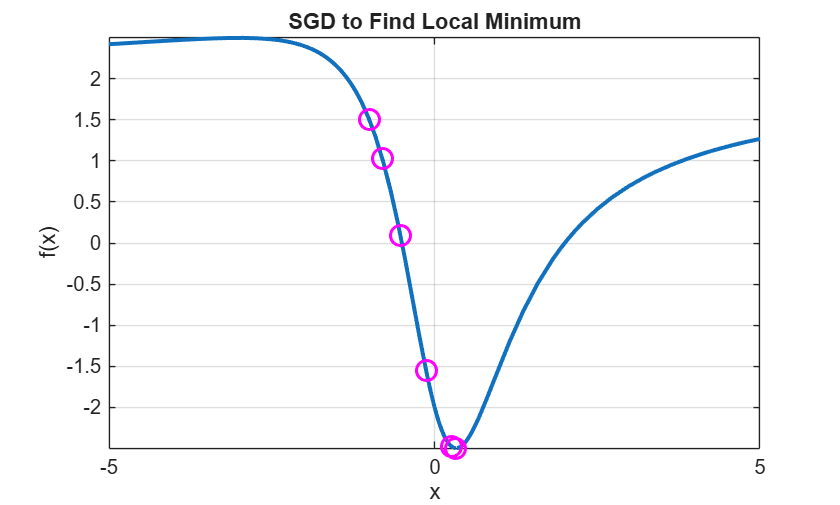

hold off;

B) Maximum?

% STOP HERE FOR INITIAL GUESSES FOR MAX!!!!!!
figure;
fplot(f, tspan, 'LineWidth', 2);
xlabel('x');
ylabel('f(x)');
title('SGD to Find Local Maximum');
grid on;
hold on;

x0 = -2;

for ii = 1:maxloops
    % Plot the current point on the function
    plot(x0, f(x0), 'm*', 'MarkerSize', 10);

    % Evaluate the gradient at the current point
    gradValue = double(dfx(x0));

    % Update x for gradient ascent (move opposite to gradient descent direction)
    x1 = x0 + alpha * gradValue;

    % Display iteration details
    if ii == 1
        fprintf('Ite   X0       X1       DFx        D2Fx\n');
    end
    fprintf('%2d   %7.3f   %7.3f   %7.3f\n', ii, x0, x1, gradValue);

    % Check if convergence criterion is met
    if abs(x1 - x0) <= tolx
        % Use second derivative test to determine if it's a maximum
        secondDeriv = double(d2fx(x1));
        if secondDeriv < 0
            disp('Local Maximum found');
        elseif secondDeriv > 0
            disp('Local Minimum found');
        else
            disp('Saddle Point or inflection point found');
        end
        break;
    end

    % Update x0 for the next iteration
    x0 = x1;
end

Ite   X0       X1       DFx        D2Fx


 1    -2.000    -2.028    -0.280
 2    -2.028    -2.054    -0.263
 3    -2.054    -2.079    -0.249
 4    -2.079    -2.103    -0.235
 5    -2.103    -2.125    -0.223
 6    -2.125    -2.146    -0.212
 7    -2.146    -2.166    -0.202
 8    -2.166    -2.186    -0.193
 9    -2.186    -2.204    -0.184
10    -2.204    -2.222    -0.177
11    -2.222    -2.239    -0.169
12    -2.239    -2.255    -0.163
13    -2.255    -2.271    -0.156
14    -2.271    -2.286    -0.150
15    -2.286    -2.300    -0.145
16    -2.300    -2.314    -0.140
17    -2.314    -2.328    -0.135
18    -2.328    -2.341    -0.130
19    -2.341    -2.353    -0.126
20    -2.353    -2.365    -0.122
21    -2.365    -2.377    -0.118
22    -2.377    -2.389    -0.114
23    -2.389    -2.400    -0.111
24    -2.400    -2.411    -0.108
25    -2.411    -2.421    -0.105
26    -2.421    -2.431    -0.102
27    -2.431    -2.441    -0.099


Local Maximum found


fprintf('Final x value: %.4f\n', x1);

Final x value: -2.4411


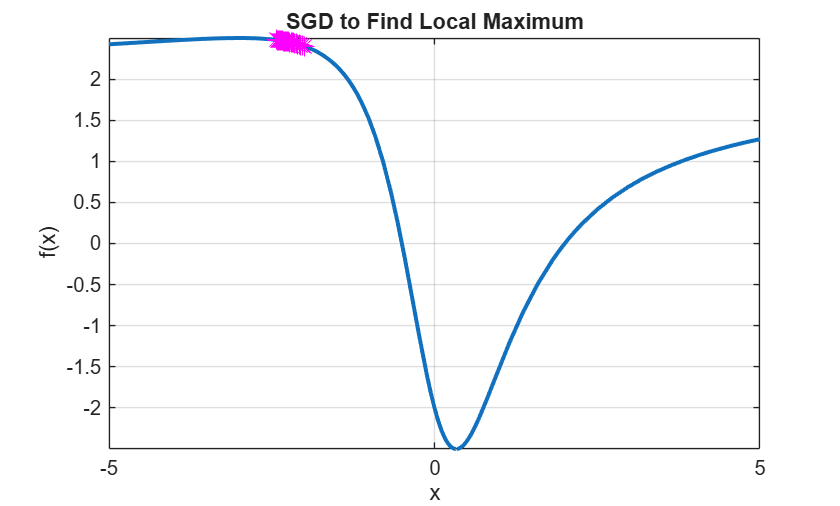

hold off;

Question 3:

You are investigating the relationship between the diameter of small blood vessels (capillaries or arterioles) and the blood flow rate in a microvascular network. The goal is to model the blood flow in relation to vessel diameter using experimental data.

Blood flow in small vessels is typically governed by the Poiseuille's Law, which describes how flow rate $Q$ depends on the radius $r$ of a cylindrical vessel:


$$Q\left(r\right)=\frac{\pi r^4 \Delta \;P}{8\mu \;L}$$


where:

- $Q$ is the flow rate

- $\Delta \;P$ is the pressure difference across a vessel

- $r$ is the radius of the vessel

- $\mu \;$ is the dynamic viscosity of the blood

- $L$ is the length of the vessel

However, in a microvascular network, the pressure difference and length may vary. A more generalized empirical form of this equation can be used for fitting, which relates the flow to the diameter of the vessels with an exponent $n$:


$$Q\left(d\right)={C\cdot d}^n$$


where:

- $Q$ is the flow rate

- $d$ is the diameter of the vessel

- $C$ is a lumped parameter that depends on viscosity and vessel length.

- $n$ is an exponent that represents the non-linearity of flow with respect to diameter.

You have experimental data collected from a microvascular system where the blood flow rate in different vessels (in mL/min) is measured along with their diameters (in micrometers).

Fit the equation $Q={C\cdot d}^n$ to the experimental data and estimate the values of $C$ and $n$, use an initial guess of $C=0\ldotp 1$ and $n=1$. Hint: Use fminsearch().


% Nonlinear Curve Fitting / fminsearch()

clear,clc
% Experimental data
diameters = [10 20 30 40 50 60 70 80]; % Diameter (µm)
flow_rate = [0.05 0.15 0.30 0.50 0.80 1.20 1.80 2.50]; % Flow Rate (mL/min)


% % Set Up

Q_model = @(d, c) c(1) * d.^c(2);
% ^  Q = C * d^n

SSE = @(c) sum((Q_model(diameters, c) - flow_rate).^2); % sum of squared errors

x0 = [0.1, 1]; % Initial guess: C = 0.1, n = 1


% % Find the parameters
params_opt = fminsearch(SSE, x0); % fminsearch for parameters

% display the found parameters
fprintf('C: %d\n', params_opt(1));

C: 8.041603e-05


fprintf('n: %3.2f\n', params_opt(2));

n: 2.36


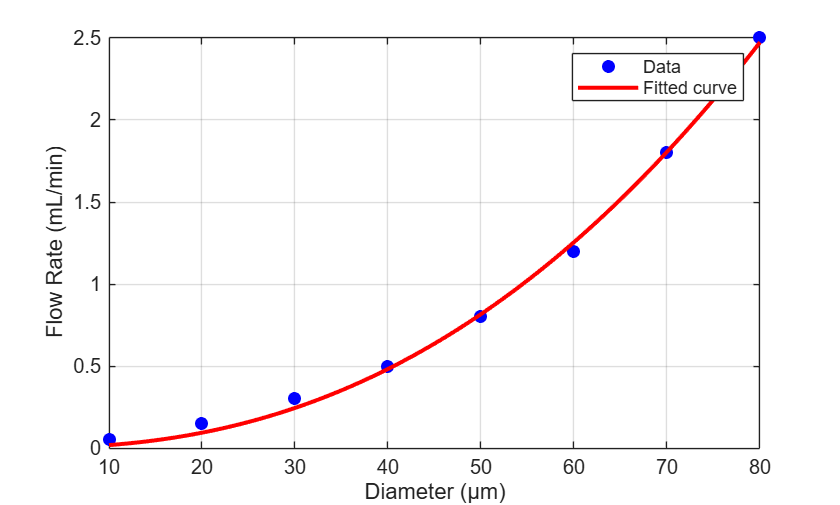


% Plot the fitted curve along with the data
figure;
plot(diameters, flow_rate, 'bo', 'MarkerFaceColor', 'b'); % Experimental data
hold on;
smooth_diameters=linspace(min(diameters), max(diameters));
fitted_flow = Q_model(smooth_diameters, params_opt);
plot(smooth_diameters, fitted_flow, 'r-', 'LineWidth', 2); % Fitted curve
hold off;
xlabel('Diameter (µm)');
ylabel('Flow Rate (mL/min)');
legend('Data', 'Fitted curve');
grid on;

Question 4:

In enzyme kinetics, substrate inhibition occurs when an excess of substrate reduces the reaction rate. The rate $v$ as a function of substrate concentration $\left\lbrack S\right\rbrack$ can be described by a non-linear equation:


$$v\left(\left\lbrack S\right\rbrack \right)=\frac{V_{\mathrm{Max}} \left\lbrack S\right\rbrack }{K_m +\left\lbrack S\right\rbrack +\frac{{\left\lbrack S\right\rbrack }^2 }{K_i }}$$


where:

- $v$ is the reaction rate

- $\left\lbrack S\right\rbrack$ is the substrate concentration

- $V_{\mathrm{Max}}$ is the maximum reaction rate

- $K_m$ is the Michaelis constant (substrate concentration at half-maximal velocity)

- $K_i$ is the inhibition constant

Fit the equation above to the provided experimental data and estimate the values of $V_{\mathrm{Maxx}}$, $K_m$, and $K_i$. Use an initial guess of $V_{\mathrm{Nax}} =8$, $K_m =1\ldotp 5$, and $K_i =15$.

clear,clc

% Known substrate concentrations (S) and reaction rates (v)
S = [0.1, 0.5, 1.0, 2.0, 5.0, 10.0, 20.0, 50.0]; % Substrate concentrations in mM
v = [0.48, 2.12, 3.45, 5.20, 6.75, 7.85, 8.40, 8.60]; % Reaction rates in mM/s




% Non-linear model
        % c(1) = Vmax (maximum reaction rate)
        % c(2) = Km (Michaelis constant)
        % c(3) = Ki (substrate inhibition constant)
model = @(S, c) (c(1) .* S) ./ (c(2) + S + (S.^2 ./ c(3)));


initial_guess = [8, 1.5, 15]; % [Vmax, Km, Ki]

SSE = @(c) sum((v - model(S, c)).^2);

estimated_params = fminsearch(SSE, initial_guess);



% display the found parameters
fprintf('Vmax = %3.2f\n', estimated_params(1)); % Display Vmax

Vmax = 9.14


fprintf('Km = %3.2f\n', estimated_params(2));   % Display Km

Km = 1.62


fprintf('Ki = %3.2f\n', estimated_params(3));   % Display Ki

Ki = 1731.02


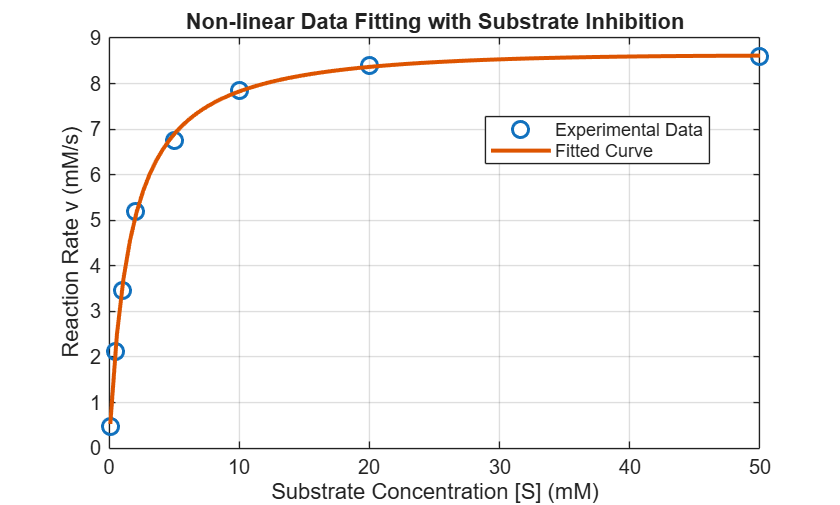



% Calculate the fitted reaction rates using the optimized parameters
S_fine = linspace(min(S), max(S)); % smooth it out
v_fit = model(S_fine, estimated_params);

figure;
plot(S, v, 'o', 'MarkerSize', 8, 'LineWidth', 1.5); % raw experimental data
hold on;
plot(S_fine, v_fit, '-', 'LineWidth', 2);          %fitted curve
hold off;
legend('Experimental Data', 'Fitted Curve', 'Location', 'Best');
xlabel('Substrate Concentration [S] (mM)');        
ylabel('Reaction Rate v (mM/s)');                   
title('Non-linear Data Fitting with Substrate Inhibition');
grid on; 

Question 5:

Newton's Law of Cooling describes the rate at which the temperature of an object changes when it is exposed to an environment with a constant temperature. The equation is:


$$T\left(t\right)=T_{\mathrm{Env}} +\left(T_0 -T_{\mathrm{Env}} \right)e^{-\mathrm{kt}}$$


where:

- $T\left(t\right)$ is the temperature of the object at time $t$

- $t$ is time

- $T_{\mathrm{Env}}$ is the ambient (environment) temperature

- $T_0$ is the initial temperature of the object

- $k$ is the cooling constant (rate of cooling)

Fit the equation above to the provided experimental data for the temperature of a metal object as it cools over time and estimate the values of $T_{\mathrm{Env}}$, $T_0$, and $k$. Use an initial guess of $T_{\mathrm{Env}} =10$, $T_0 =80$, and $k=0\ldotp 5$.

clear;clc;
% Time (t) in minutes
t = [0, 2, 4, 6, 8, 10];

% Measured temperature (T) in °C
T = [100.0, 80.4, 65.2, 54.5, 47.1, 41.5];






% Non-linear cooling model:
    % c(1) = T_env (ambient temperature)
    % c(2) = T_0 (initial temperature of the object)
    % c(3) = k (cooling constant)
model = @(t, c) c(1) + (c(2) - c(1)) .* exp(-c(3) .* t);


initial_guess = [10, 80, 0.5]; %  [T_env, T_0, k]

SSE = @(c) sum((T - model(t, c)).^2);

estimated_params = fminsearch(SSE, initial_guess);


% Display the estimated parameters
disp('Estimated Parameters:');

Estimated Parameters:


disp(['T_env = ', num2str(estimated_params(1)), ' °C']); % Ambient temperature

T_env = 26.5399 °C


disp(['T_0 = ', num2str(estimated_params(2)), ' °C']);   % Initial temperature

T_0 = 100.1454 °C


disp(['k = ', num2str(estimated_params(3)), ' 1/min']); % Cooling constant

k = 0.15988 1/min


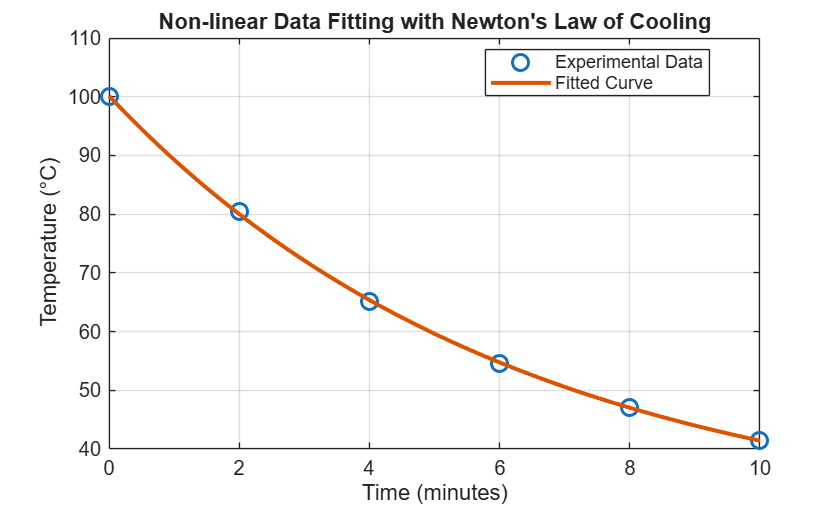


% Calculate the fitted temperatures using the optimized parameters
t_fine = linspace(min(t), max(t), 100);
T_fit = model(t_fine, estimated_params);

figure;
plot(t, T, 'o', 'MarkerSize', 8, 'LineWidth', 1.5); % experimental data
hold on;
plot(t_fine, T_fit, '-', 'LineWidth', 2);           % fitted curve
hold off;
legend('Experimental Data', 'Fitted Curve', 'Location', 'best');
xlabel('Time (minutes)');  
ylabel('Temperature (°C)');                        
title('Non-linear Data Fitting with Newton''s Law of Cooling');
grid on;                                         